clear;

global Imean;
global Iamp;
global YY;
global XX;

tic;
% step_load_image("samples/bottles", "png", false);
step_load_image("samples/chairs", "png", false);
% step_load_image("samples/dinosaur", "png", false);
% step_load_image("samples/potdng", "tif", true);
% step_load_image("samples/inside", "tif", true);
% step_load_image("samples/cars", "tif", true);
% step_load_image("samples/football", "tif", true);
% step_load_image("samples/zoom", "tif", true);
% step_load_image("samples/window", "tif", true);
toc;

fun_imshowlin(Imean(YY, XX, :));
fun_imshowlin(Iamp(YY, XX, :));

fun_imwritelin(Imean(YY, XX, :), '1mean');
fun_imwritelin(Iamp(YY, XX, :), '1amp');

% Tile-based estimate
clear Id;
clear Is;
clear k;

tic;
k = step_tile_estimate(16);
toc;

fun_imshowlin(0.25 .* k(YY, XX));
fun_imshowlin(Imean(YY, XX, :) - k(YY, XX) .* Iamp(YY, XX, :));
fun_imshowlin(k(YY, XX) .* Iamp(YY, XX, :));

fun_imwritelin(0.25 * k(YY, XX), '2weightmapt');
fun_imwritelin(Imean(YY, XX, :) - k(YY, XX) .* Iamp(YY, XX, :), '2diffuset');
fun_imwritelin(k(YY, XX) .* Iamp(YY, XX, :), '2speculart');

% Pyramid iterations
tic;
k = step_tile_estimate(16); % Restart to clear memory.
k = step_iterations(k);
toc;

Elapsed time is 6.453599 seconds.


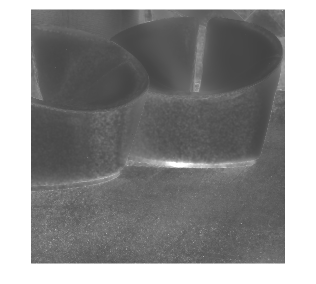

Is = k .* Iamp;
Id = Imean - Is;

fun_imshowlin(0.05 * k(YY, XX));

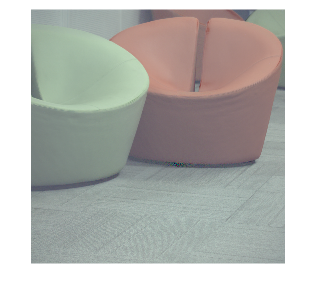

fun_imshowlin(Id(YY, XX, :));

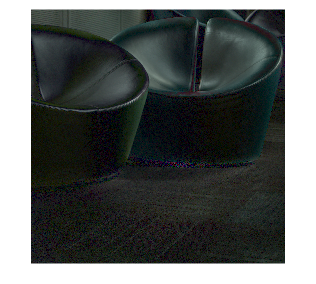

fun_imshowlin(Is(YY, XX, :));

fun_imwritelin(0.25 * k(YY, XX), '3weightmap');
fun_imwritelin(Id(YY, XX, :), '3diffuse');
fun_imwritelin(Is(YY, XX, :), '3specular');

return;

% fun_imwritelin(2 * Id(770:1100, 500:1850, :), '3diffusecut');
% fun_imwritelin(2 * Is(770:1100, 500:1850, :), '3specularcut');

% Textures
fun_imwritelin(fun_adjust_textures(Id(YY, XX, :), [1150 670], 0.2, [774 400 1220 1000], [66 133 244] ./ 255.0) + Is(YY, XX, :), '4textures');

% Highlights
fun_imwritelin(Id(YY, XX, :) + fun_adjust_highlights(Is(YY, XX, :), 128.0, 1.5), '4highlights');

% Tonemapping
fun_imwritelin(fun_tonemap(Imean(YY, XX, :), 0.67, 1.0), '4tonemap');
fun_imwritelin(fun_tonemap(Id(YY, XX, :), 0.67, 1.0) + Is(YY, XX, :), '4tonemapdiffuse');

% All at once.
tic;
fun_imwritelin(fun_tonemap(fun_adjust_textures(Id(YY, XX, :), [1150 670], 0.2, [774 400 1220 1000], [66 133 244] ./ 255.0), 0.67, 1.0) + fun_adjust_highlights(Is(YY, XX, :), 128.0, 1.5), '5pipeline');
toc;